clc;
clear;
close all;

global x_c y_c a S L
syms L S theta1 theta2 theta3 a x_c y_c

r_base = 290; %(mm)
r_plat = 130; 

%Point B centr of base
B = [r_base*sqrt(3)/2; r_base/2; 0];

%Point C centre of platform
C = [x_c; y_c; 0];


%test variables
S_val = 170;
L_val = 130;
x_c_val = r_base*sqrt(3)/2;
y_c_val = r_base/2;
a_val = 0;

%FIRST LEG
%calculate the point M1
PB1 = [0;0;0];

M1 = PB1 + [S*cos(theta1);S*sin(theta1);0]

$$M1 = \left(\begin{array}{c} S\,\cos\left(\theta_{1}\right)\\ S\,\sin\left(\theta_{1}\right)\\ 0 \end{array}\right)$$


%BPP1 = Rbc*CPP1 + BC
CPP1 = [-r_plat*cos(pi/6);-r_plat*sin(pi/6);0];
BC = C-B;
%rot
Rbc = [cos(a) -sin(a) 0;sin(a) cos(a) 0;0 0 1];
BPP1 = Rbc*CPP1 + BC;

%calculate point PP1 (%BPP1-BPB1)
PP1 = BPP1 - (PB1-B)

$$PP1 = \left(\begin{array}{c} x_{c}+65\,\sin\left(a\right)-65\,\sqrt{3}\,\cos\left(a\right)\\ y_{c}-65\,\cos\left(a\right)-65\,\sqrt{3}\,\sin\left(a\right)\\ 0 \end{array}\right)$$

%PP1 = BPP1 + B

%psi
psi1 = simplify(atan2(PP1(2,1)-M1(2,1), PP1(1,1)- M1(1,1)))

$$psi1 = \text{atan2}\left(y_{c}-65\,\cos\left(a\right)-65\,\sqrt{3}\,\sin\left(a\right)-S\,\sin\left(\theta_{1}\right),x_{c}+65\,\sin\left(a\right)-65\,\sqrt{3}\,\cos\left(a\right)-S\,\cos\left(\theta_{1}\right)\right)$$


%phi
phi1 = a + pi/6;
c1 = atan2(y_c-r_plat*sin(phi1),x_c-r_plat*cos(phi1));
acos_arg1 = (S^2 - L^2 + (x_c - r_plat * cos(phi1))^2 + (y_c - r_plat * sin(phi1))^2) / ...
           (2 * S * sqrt((x_c - r_plat * cos(phi1))^2 + (y_c - r_plat * sin(phi1))^2));
d1 = acos(acos_arg1);

%phi
phi1_val = subs(phi1, a, a_val);

%theta1
theta1_1 = subs(c1+d1,[x_c y_c a S L],[x_c_val y_c_val a_val S_val L_val]);
theta1_2 = subs(c1-d1,[x_c y_c a S L],[x_c_val y_c_val a_val S_val L_val]);
double(theta1_1)

ans = 1.3313

double(theta1_2)

ans = -0.2841


%psi
psi_1 = subs(psi1, [x_c y_c a S L theta1],[x_c_val y_c_val a_val S_val L_val theta1_1]);
psi_2 = subs(psi1, [x_c y_c a S L theta1],[x_c_val y_c_val a_val S_val L_val theta1_2]);
double(psi_1)

ans = -0.7142

double(psi_2)

ans = 1.7613


%PP1
PP1_val = subs(PP1, [x_c y_c a], [x_c_val y_c_val a_val]);

%SECOND LEG
%calculate the point M1
PB2 = [r_base*sqrt(3);0;0];

M2 = PB2 + [S*cos(theta2);S*sin(theta2);0] 

$$M2 = \left(\begin{array}{c} S\,\cos\left(\theta_{2}\right)+\frac{8836462413088473}{17592186044416}\\ S\,\sin\left(\theta_{2}\right)\\ 0 \end{array}\right)$$


%BPP2 = Rbc*CPP2 + BC
CPP2 = [-r_plat*cos(pi/6 + 2*pi/3);-r_plat*sin(pi/6 + 2*pi/3);0]; %offset of 120 degrees
BC2 = C-B; 
%rot
Rbc2 = [cos(a) -sin(a) 0;sin(a) cos(a) 0;0 0 1];
BPP2 = Rbc2*CPP2 + BC2;

%calculate point PP2 (%BPP2-BPB2)
PP2 = BPP2 + B;

%psi
psi2 = simplify(atan2(PP2(2,1)-M2(2,1), PP2(1,1) - M2(1,1)))

$$psi2 = \text{atan2}\left(y_{c}-65\,\cos\left(a\right)+65\,\sqrt{3}\,\sin\left(a\right)-S\,\sin\left(\theta_{2}\right),x_{c}+65\,\sin\left(a\right)+65\,\sqrt{3}\,\cos\left(a\right)-S\,\cos\left(\theta_{2}\right)-\frac{8836462413088473}{17592186044416}\right)$$


%because of point chage relative to centre, we need to deduct pi
%phi
phi2 = a + 5*pi/6;
c2 = atan2(y_c-r_plat*sin(pi - phi2), r_base*sqrt(3)-x_c-r_plat*cos(pi - phi2));
acos_arg2 = (S^2 - L^2 + (r_base*sqrt(3)-x_c-r_plat*cos(pi - phi2))^2 + (y_c - r_plat * sin(pi - phi2))^2) / ...
           (2 * S * sqrt((r_base*sqrt(3)-x_c-r_plat*cos(pi - phi2))^2 + (y_c - r_plat * sin(pi - phi2))^2));
d2 = acos(acos_arg2);

%theta2 (off set of pi due to quadrant)
theta2_1 = subs(pi-(c2+d2),[x_c y_c a S L],[x_c_val y_c_val a_val S_val L_val]);
theta2_2 = subs(pi-(c2-d2),[x_c y_c a S L],[x_c_val y_c_val a_val S_val L_val]);
double(theta2_1)

ans = 1.8103

double(theta2_2)

ans = 3.4257


%psi2
psi2_1 = subs(pi-psi2, [x_c y_c a S L theta2],[x_c_val y_c_val a_val S_val L_val theta2_1]);
psi2_2 = subs(pi-psi2, [x_c y_c a S L theta2],[x_c_val y_c_val a_val S_val L_val theta2_2]);
double(psi2_1)

ans = 5.5690

double(psi2_2)

ans = 1.7613


%PP2
PP2_val = subs(PP2, [x_c y_c a], [x_c_val y_c_val a_val]);

%Third LEG
%calculate the point M3
PB3 = [r_base*sqrt(3)/2;r_base*3/2;0];

M3 = PB3 + [S*cos(theta3);S*sin(theta3);0] 

$$M3 = \left(\begin{array}{c} 145\,\sqrt{3}+S\,\cos\left(\theta_{3}\right)\\ S\,\sin\left(\theta_{3}\right)+435\\ 0 \end{array}\right)$$


%BPP3 = Rbc*CPP3 + BC
CPP3 = [-r_plat*cos(pi/6 + pi*4/3);-r_plat*sin(pi/6 + pi*4/3);0];
BC3 = C-B; 
%rot
Rbc3 = [cos(a) -sin(a) 0;sin(a) cos(a) 0;0 0 1];
BPP3 = Rbc3*CPP3 + BC3;

%calculate point PP2 (%BPP2-BPB2)
%PP3 = BPP3 - (PB3-B)
PP3 = BPP3 + B;

%psi3
psi3 = simplify(atan2(PP3(2,1)-M3(2,1), PP3(1,1) - M3(1,1)))

$$psi3 = \text{angle}\left(x_{c}+y_{c}\,\mathrm{i}+\cos\left(a\right)\,\left(\frac{3784034109391385}{158456325028528675187087900672}+130\,\mathrm{i}\right)+\sin\left(a\right)\,\left(-130+\frac{3784034109391385}{158456325028528675187087900672}\,\mathrm{i}\right)-145\,\sqrt{3}-S\,\cos\left(\theta_{3}\right)-S\,\sin\left(\theta_{3}\right)\,\mathrm{i}-435\,\mathrm{i}\right)$$


%phi (phi1 + 240 degrees due to gemotry)
phi3 = a + 9*pi/6;

c3 = atan2(r_base*3/2 - y_c- r_plat*sin(2*pi - phi3), r_base*sqrt(3)/2 - x_c- r_plat*cos(2*pi - phi3));
acos_arg2 = (S^2 - L^2 + (r_base*sqrt(3)/2 - x_c- r_plat*cos(2*pi - phi3))^2 + (r_base*3/2 - y_c - r_plat*sin(2*pi - phi3))^2) / ...
            (2 * S * sqrt((r_base*sqrt(3)/2 - x_c- r_plat*cos(2*pi - phi3))^2 + (r_base*3/2 - y_c - r_plat*sin(2*pi - phi3))^2));
d3 = acos(acos_arg2);

%theta3 (off set of 2pi due to quadrant)
theta3_1 = subs(2*pi-(c3+d3),[x_c y_c a S L],[x_c_val y_c_val a_val S_val L_val]);
theta3_2 = subs(2*pi-(c3-d3),[x_c y_c a S L],[x_c_val y_c_val a_val S_val L_val]);
double(theta3_1)

ans = 3.9047

double(theta3_2)

ans = 5.5201


%psi3
psi3_1 = subs(2*pi-psi3, [x_c y_c a S L theta3],[x_c_val y_c_val a_val S_val L_val theta3_1]);
psi3_2 = subs(2*pi-psi3, [x_c y_c a S L theta3],[x_c_val y_c_val a_val S_val L_val theta3_2]);
double(psi3_1)

ans = 6.6162

double(psi3_2)

ans = 9.0917


%PP3
PP3_val = subs(PP3, [x_c y_c a], [x_c_val y_c_val a_val]);

%end effector equilateral triangle
p_length = r_plat * sqrt(3);
p = nsidedpoly(3, 'Center', [x_c_val, y_c_val], 'SideLength', p_length);
p_rotated=rotate(p,rad2deg(a_val),[x_c_val, y_c_val]);

%validate
p.Vertices

ans =   138.5641   80.0000
  251.1474  275.0000
  363.7307   80.0000


double(PP1_val')

ans =   138.5641   80.0000         0


double(PP2_val')

ans =   363.7307   80.0000         0


double(PP3_val')

ans =   251.1474  275.0000         0


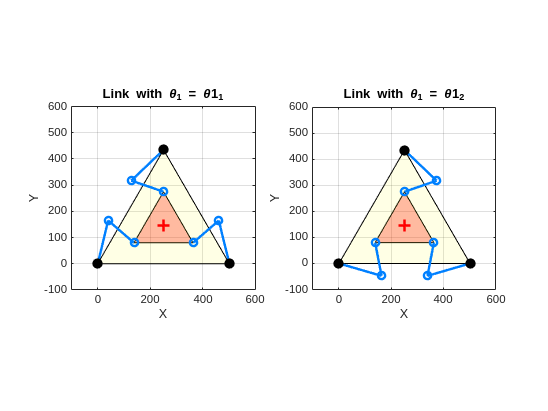


%calculate endpoints for both angles for M
x_end1 = S_val * cos(theta1_1);
y_end1 = S_val * sin(theta1_1);
x_end2 = S_val * cos(theta1_2);
y_end2 = S_val * sin(theta1_2);

x2_end1 = r_base*sqrt(3) - (S_val * cos(pi - theta2_1));
y2_end1 = S_val * sin(theta2_1);
x2_end2 = r_base*sqrt(3) - (S_val * cos(pi - theta2_2));
y2_end2 = S_val * sin(theta2_2);

x3_end1 = r_base*sqrt(3)/2 + (S_val * cos(2*pi - theta3_1));
y3_end1 = r_base*3/2 + S_val * sin(theta3_1);
x3_end2 = r_base*sqrt(3)/2 + (S_val * cos(2*pi - theta3_2));
y3_end2 = r_base*3/2 + S_val * sin(theta3_2);

%calculate startpoints for PP
x_pp_end1 = PP1_val(1,1) - L_val * cos(psi_1);
y_pp_end1 = PP1_val(2,1) - L_val * sin(psi_1);
x_pp_end2 = PP1_val(1,1) - L_val * cos(psi_2);
y_pp_end2 = PP1_val(2,1) - L_val * sin(psi_2);

x_pp2_end1 = PP2_val(1,1) + L_val * cos(psi2_1);
y_pp2_end1 = PP2_val(2,1) - L_val * sin(psi2_1);
x_pp2_end2 = PP2_val(1,1) + L_val * cos(psi2_2);
y_pp2_end2 = PP2_val(2,1) - L_val * sin(psi2_2);

x_pp3_end1 = PP3_val(1,1) - L_val * cos(psi3_1);
y_pp3_end1 = PP3_val(2,1) + L_val * sin(psi3_1);
x_pp3_end2 = PP3_val(1,1) - L_val * cos(psi3_2);
y_pp3_end2 = PP3_val(2,1) + L_val * sin(psi3_2);

%base
b_length = r_base * sqrt(3);
b = nsidedpoly(3, 'Center', [B(1,1), B(2,1)], 'SideLength', b_length);

%plots
figure;

%axis limits
x_lim = [-100, 600];
y_lim = [-100, 600];

% Subplot 1: Link with theta1_1
subplot(1, 2, 1); % 1 row, 2 columns, first subplot
fill(p_rotated.Vertices(:, 1), p_rotated.Vertices(:, 2), 'red', 'FaceAlpha', 0.3);
hold on;
fill(b.Vertices(:, 1), b.Vertices(:, 2), 'yellow', 'FaceAlpha', 0.1);
plot(x_c_val, y_c_val, 'r+', 'MarkerSize', 10, 'LineWidth', 2); % Plot the center point
plot([0, x_end1], [0, y_end1], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 1-1
plot([x_pp_end1, PP1_val(1,1)], [y_pp_end1, PP1_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 1-2
plot([r_base*sqrt(3), x2_end1], [0, y2_end1], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2-1
plot([x_pp2_end1, PP2_val(1,1)], [y_pp2_end1, PP2_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2-2
plot([r_base*sqrt(3)/2, x3_end1], [r_base*3/2, y3_end1], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 3-1
plot([x_pp3_end1, PP3_val(1,1)], [y_pp3_end1, PP3_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 3-2
plot(0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); %origin points
plot(r_base*sqrt(3), 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
plot(r_base*sqrt(3)/2, r_base*3/2, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
title('Link with \theta_1 = \theta1_1');
xlabel('X');
ylabel('Y');
axis equal;
xlim(x_lim);
ylim(y_lim);
grid on;

% Subplot 2: Link with theta1_2
subplot(1, 2, 2); % 1 row, 2 columns, second subplot
fill(p_rotated.Vertices(:, 1), p_rotated.Vertices(:, 2), 'red', 'FaceAlpha', 0.3);
hold on;
fill(b.Vertices(:, 1), b.Vertices(:, 2), 'yellow', 'FaceAlpha', 0.1);
plot(x_c_val, y_c_val, 'r+', 'MarkerSize', 10, 'LineWidth', 2); % Plot the center point
plot([0, x_end2], [0, y_end2], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 1
plot([x_pp_end2, PP1_val(1,1)], [y_pp_end2, PP1_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2
plot([r_base*sqrt(3), x2_end2], [0, y2_end2], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2-1
plot([x_pp2_end2, PP2_val(1,1)], [y_pp2_end2, PP2_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 2-2
plot([r_base*sqrt(3)/2, x3_end2], [r_base*3/2, y3_end2], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 3-1
plot([x_pp3_end2, PP3_val(1,1)], [y_pp3_end2, PP3_val(2,1)], '-o', 'LineWidth', 2, 'Color', [0, 0.5, 1]); % Link 3-2
plot(0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); %origin points
plot(r_base*sqrt(3), 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k'); %origin points
plot(r_base*sqrt(3)/2, r_base*3/2, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
title('Link with \theta_1 = \theta1_2');
xlabel('X');
ylabel('Y');
axis equal;
xlim(x_lim);
ylim(y_lim);
grid on;

%test 
double([x_pp_end1 y_pp_end1])

ans =    40.3297  165.1470


double(subs(M1, [S theta1], [S_val theta1_1])')

ans =    40.3297  165.1470         0



double([x_pp2_end1 y_pp2_end1])

ans =   461.9651  165.1470


double(subs(M2, [S theta2], [S_val theta2_1])')

ans =   461.9651  165.1470         0



double([x_pp3_end1 y_pp3_end1])

ans =   128.2907  317.5000


double(subs(M3, [S theta3], [S_val theta3_1])')

ans =   128.2907  317.5000         0


%SOLVE IK
theta1_1_expr = c1+d1;
theta1_2_expr = c1-d1;
theta2_1_expr = pi-(c2+d2);
theta2_2_expr = pi-(c2-d2);
theta3_1_expr = 2*pi-(c3+d3);
theta3_2_expr = 2*pi-(c3-d3);

function [thetaSol, feasible] = solveIK(xTry, yTry, a_val, ...
                                        S_val, L_val)

    global x_c y_c a S L
    global theta1_1_expr theta1_2_expr ...
           theta2_1_expr theta2_2_expr ...
           theta3_1_expr theta3_2_expr

    %calculate thetas
    t1_1 = subs(theta1_1_expr, [x_c y_c a S L], [xTry yTry a_val S_val L_val]);
    t1_2 = subs(theta1_2_expr, [x_c y_c a S L], [xTry yTry a_val S_val L_val]);

    t2_1 = subs(theta2_1_expr, [x_c y_c a S L], [xTry yTry a_val S_val L_val]);
    t2_2 = subs(theta2_2_expr, [x_c y_c a S L], [xTry yTry a_val S_val L_val]);

    t3_1 = subs(theta3_1_expr, [x_c y_c a S L], [xTry yTry a_val S_val L_val]);
    t3_2 = subs(theta3_2_expr, [x_c y_c a S L], [xTry yTry a_val S_val L_val]);

    %to double
    t1_1 = double(t1_1);  t1_2 = double(t1_2);
    t2_1 = double(t2_1);  t2_2 = double(t2_2);
    t3_1 = double(t3_1);  t3_2 = double(t3_2);

    %check all possible configurations

    combos = [
       t1_1, t2_1, t3_1;
       t1_1, t2_1, t3_2;
       t1_1, t2_2, t3_1;
       t1_1, t2_2, t3_2;
       t1_2, t2_1, t3_1;
       t1_2, t2_1, t3_2;
       t1_2, t2_2, t3_1;
       t1_2, t2_2, t3_2
    ];

    feasible = false;           
    thetaSol = [NaN, NaN, NaN];

    for i = 1:size(combos,1)
        tCandidate = combos(i,:);
        
        %check for imaginary parts
        if ~isreal(tCandidate) || any(imag(tCandidate) ~= 0)
            %skip not feasible
            continue;
        end

        %else it is possible config
        feasible = true;
        thetaSol = tCandidate;  %store solution
        break;                  %only first valid sol
    end

end


%WORKSPACE calculate
%STEP 1 calculate the search grid, in this case the base triangle
b.Vertices

ans =          0         0
  251.1474  435.0000
  502.2947         0


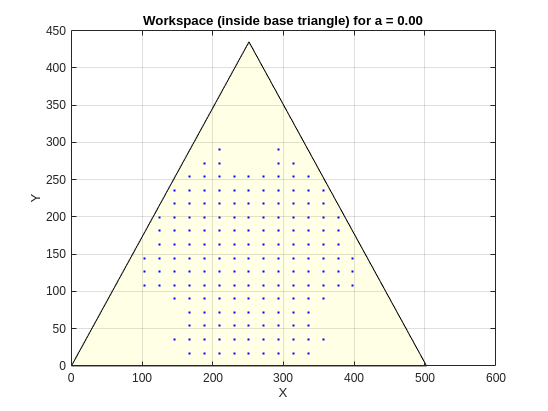

% bounding box that covers the triangle fully
x_min = min(b.Vertices(:,1)) - 1;
x_max = max(b.Vertices(:,1)) + 1;
y_min = min(b.Vertices(:,2)) - 1;
y_max = max(b.Vertices(:,2)) + 1;

%2D grid
numSteps = 25;  %detail
x_vals = linspace(x_min, x_max, numSteps);
y_vals = linspace(y_min, y_max, numSteps);

%check if each (Xgrid(i),Ygrid(i)) is in base triangle
[Xgrid, Ygrid] = meshgrid(x_vals, y_vals);
[in, on] = inpolygon(Xgrid, Ygrid, b.Vertices(:,1), b.Vertices(:,2));

%get points that are inside base platform
insideIdx = (in | on);  %boolean mask 
xInside = Xgrid(insideIdx);
yInside = Ygrid(insideIdx);

%STEP 2 calculate IK for mesh points - IF THEY EXIST! (exclude imaginary)
%for a of 10 degrees or pi/18
%a_val = pi/18;
%a_val = pi/16;
%a_val = pi/14;
a_val = 0;

feasiblePoints = [];

for i = 1:numel(xInside)
    xTry = xInside(i);
    yTry = yInside(i);

    [thetaSol, feasible] = solveIK(xTry, yTry, a_val, ...
                                   S_val, L_val);
    if feasible
        feasiblePoints = [feasiblePoints; xTry, yTry];
    end
end

%STEP 3 plot workspace
figure; 
axis equal;

fill(b.Vertices(:, 1), b.Vertices(:, 2), 'yellow', 'FaceAlpha', 0.1);
hold on; 
plot(feasiblePoints(:,1), feasiblePoints(:,2), 'b.', 'MarkerSize', 5);

xlabel('X'); ylabel('Y');
title(sprintf('Workspace (inside base triangle) for a = %.2f', a_val));
grid on;